# Exercice 11 - Optimisation multi-objectifs 

## Données

Un dispatcher d'énergies dispose de 5  centrales thermiques de différentes technologiques qui produisent de l'électricité. Il est capable de prédire le coût de chaque centrale à partir d'une relation de type : 


$$C_I \left(P_I \right)=a_I {\left(P_I \right)}^2 +b_I {\left(P_I \right)} +c_I$$


$C_I$ est le coût de production selon la puissance produite ($P_I$) pour l'unité *I*. 

Chaque centrale a des limites de production : $P_{I,\min } {\le P}_I \le P_{I,\max }$

Chaque centrale produit des émissions polluantes. Le dispatcher dispose de relation pour estimer la quantité totale ($T_I$) de polluants produite en kg/j par chaque centrale en fonction de sa puissance thermique ($P_I$) :  


$$T_I \left(P_I \right)=d_I {\left(P_I \right)}^2 +e_I {\left(P_I \right)} +f_I$$


Les données des 5 centrales sont disponibles dans le fichier `data_Exercice11.mat` (`load data_Exercice11`): coefficients `A, B, C, D, E` et `F` des deux formules ci-dessus ainsi que `Pmin` et `Pmax`. 

Toutes les puissances sont exprimées en MW.

clear 

load data_Exercice11

## Partie 1

Demande=600;
N=5; %nb de centrale

%Fonction objectif
fobj1=@(x) (A'*(x.^2)'+B'*x'+sum(C))

fobj1 = function_handle with value:
    @(x)(A'*(x.^2)'+B'*x'+sum(C))



%contraintes linéaires inégalité
Aineq=[];
Bineq=[];

%contraintes linéaires égalité
Aeq=[1,1,1,1,1];
Beq=[Demande];

%bornes
lb=Pmin;
ub=Pmax;

%Initialisation
x0=[50,110,80,150,30];

options = optimoptions('fmincon');
[x,fval,flag,out,lambda,grad]=fmincon(fobj1,x0,Aineq,Bineq,Aeq,Beq,lb,ub,'',options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


%Résultats
disp(x)

  168.8996  125.3491  125.6602  127.0912   53.0000



disp(fval)

   3.0045e+05



Ndemande=10

Ndemande = 10

Pdemande=zeros(N,Ndemande)

Pdemande =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


Fdemande=zeros(1,Ndemande)

Fdemande =      0     0     0     0     0     0     0     0     0     0


Liste_demande=linspace(sum(Pmin),sum(Pmax),Ndemande)

Liste_demande =   281.0000  360.6667  440.3333  520.0000  599.6667  679.3333  759.0000  838.6667  918.3333  998.0000


for i =1:Ndemande
    beq=Liste_demande(i)
    [x,fval,flag,out,lambda,grad]=fmincon(fobj1,x0,Aineq,Bineq,Aeq,beq,lb,ub,'',options);
    if flag>0
    Pdemande(:,i)=x;
    Fdemande(i)=fval
    end
end

beq = 281


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Fdemande = 	1.0e+04 *

    8.4038         0         0         0         0         0         0         0         0         0


beq = 360.6667


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Fdemande = 	1.0e+05 *

    0.8404    1.0927         0         0         0         0         0         0         0         0


beq = 440.3333


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Fdemande = 	1.0e+05 *

    0.8404    1.0927    1.5911         0         0         0         0         0         0         0


beq = 520


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Fdemande = 	1.0e+05 *

    0.8404    1.0927    1.5911    2.2371         0         0         0         0         0         0


beq = 599.6667


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Fdemande = 	1.0e+05 *

    0.8404    1.0927    1.5911    2.2371    3.0010         0         0         0         0         0


beq = 679.3333


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Fdemande = 	1.0e+05 *

    0.8404    1.0927    1.5911    2.2371    3.0010    3.8827         0         0         0         0


beq = 759


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Fdemande = 	1.0e+05 *

    0.8404    1.0927    1.5911    2.2371    3.0010    3.8827    4.8885         0         0         0


beq = 838.6667


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Fdemande = 	1.0e+05 *

    0.8404    1.0927    1.5911    2.2371    3.0010    3.8827    4.8885    6.0586         0         0


beq = 918.3333


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Fdemande = 	1.0e+05 *

    0.8404    1.0927    1.5911    2.2371    3.0010    3.8827    4.8885    6.0586    7.4521         0


beq = 998


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Fdemande = 	1.0e+05 *

    0.8404    1.0927    1.5911    2.2371    3.0010    3.8827    4.8885    6.0586    7.4521    9.1104


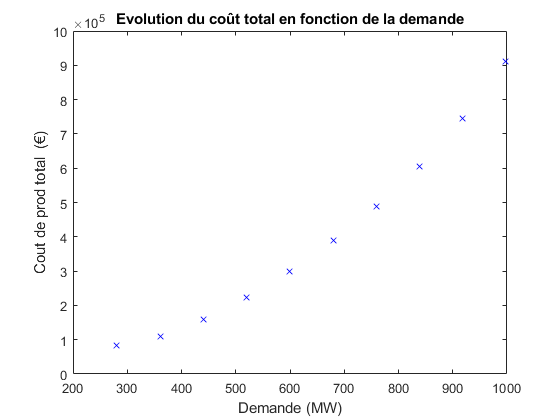


%Graphiques

figure
plot(Liste_demande,Fdemande,'xb')
xlabel('Demande (MW)')
ylabel('Cout de prod total  (€)')
title(sprintf('Evolution du coût total en fonction de la demande'))

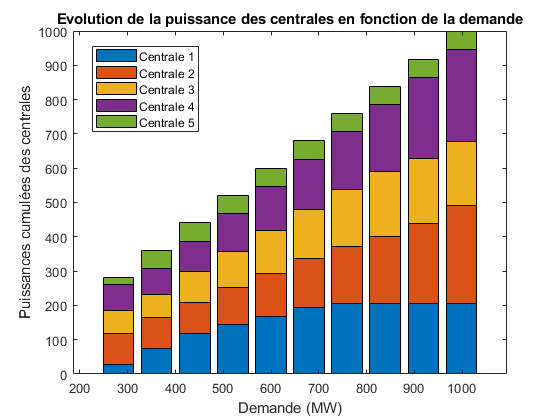

figure
bar(Liste_demande,Pdemande,'stacked')
xlabel('Demande (MW)')
ylabel('Puissances cumulées des centrales')
title(sprintf(['Evolution de la puissance des centrales en fonction de la demande']))
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")

## Partie 2

%Fonction objectif

fobj2=@(x) (D'*(x.^2)'+E'*x'+sum(F))

fobj2 = function_handle with value:
    @(x)(D'*(x.^2)'+E'*x'+sum(F))



Demande2=400

Demande2 = 400

%contraintes linéaires inégalité
Aineq2=[];
Bineq2=[];

%contraintes linéaires égalité
Aeq2=[1,1,1,1,1];
Beq2=[Demande2];

%bornes
lb2=[0,0,0,0,0];
ub2=[inf,inf,inf,inf,inf];

[x2,fval2,flag2,out2,lambda2,grad2]=fmincon(fobj2,x0,Aineq2,Bineq2,Aeq2,Beq2,lb2,ub2,'',options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


[x,fval,flag,out,lambda,grad]=fmincon(fobj1,x0,Aineq,Bineq,Aeq,Beq2,lb,ub,'',options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


disp(fval2)

   7.2585e+04



disp(x2)

   93.0641   48.6252   36.8669  168.7485   52.6953



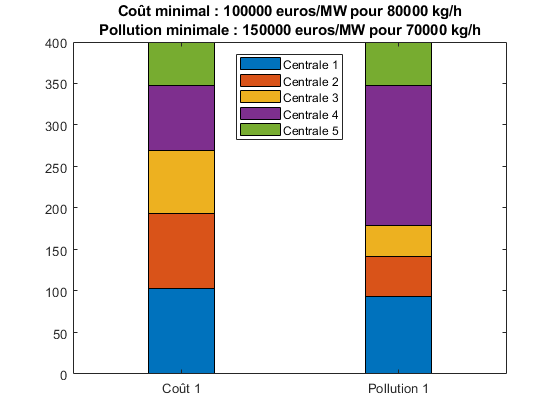


%graphiques
Cate = categorical([{'Coût 1'}, {'Pollution 1'}]);
P = x;
Q =x2;
C1=1e5; Pol1=8e4; C2=1.5e5; Pol2=7e4;
bar(Cate,[P;Q],0.3,'stacked')
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")
title(sprintf('Coût minimal : %3.0f euros/MW pour %4.0f kg/h\nPollution minimale : %3.0f euros/MW pour %4.0f kg/h',...
    C1,Pol1,C2,Pol2))

## Partie 3

fobj3=@(x,w) w*fobj1(x) + (1-w)*fobj2(x)

fobj3 = function_handle with value:
    @(x,w)w*fobj1(x)+(1-w)*fobj2(x)



Aeq3=Aeq;
Beq3=Beq2;
Aineq3=[];
Bineq3=[];
lb3=Pmin;
ub3=ub2;
[x3,fval3,flag3,out3,lambda3,grad3]=fmincon(@(x) fobj3(x,0.5),x0,[],[],Aeq3,Beq3,lb3,ub3,'',options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


%Graphiques
Npareto=50;

Npareto = 50

F1=zeros(1,Npareto);

F1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


F2=zeros(1,Npareto);

F2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


W=linspace(0,1,Npareto);
for i=1:Npareto
    [x3,fval3,flag3,out3,lambda3,grad3]=fmincon(@(x) fobj3(x,W(i)),x0,[],[],Aeq3,Beq3,lb3,ub3,'',options);
    F1(1,i)=fobj1(x3);
    F2(1,i)=fobj2(x3);
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

X=F1;
Y=F2;
Z=W;

Z =          0    0.0204    0.0408    0.0612    0.0816    0.1020    0.1224    0.1429    0.1633    0.1837    0.2041    0.2245    0.2449    0.2653    0.2857    0.3061    0.3265    0.3469    0.3673    0.3878    0.4082    0.4286    0.4490    0.4694    0.4898    0.5102    0.5306    0.5510    0.5714    0.5918    0.6122    0.6327    0.6531    0.6735    0.6939    0.7143    0.7347    0.7551    0.7755    0.7959    0.8163    0.8367    0.8571    0.8776    0.8980    0.9184    0.9388    0.9592    0.9796    1.0000


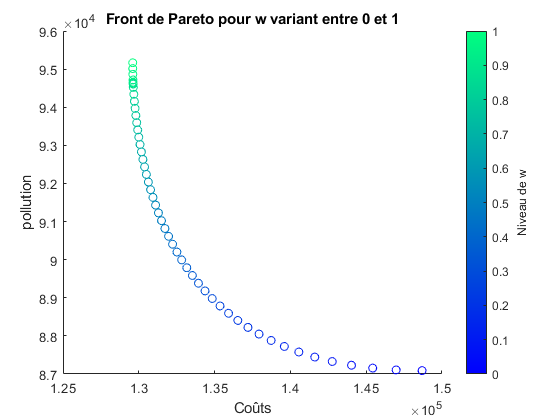

scatter(X,Y,[],Z)
colormap winter
c = colorbar;
c.Label.String = 'w';
xlabel('Coûts')
ylabel('pollution')
title('Front de Pareto pour w variant entre 0 et 1')

## Conclusions

A partir de l'ensemble des résultats obtenus, quelles sont vos conclusions générales sur l'optimum de fonctionnement ?  

L'importance de la fonction objectif est révélée dans cet exercice, le fonctionnement des centrales est totalement différent si l'on considère l'aspect économique ou bien l'aspect écologique.

Le front de Pareto nous permet de déterminer le cout de fonctionnement des centrales si on choisit un seuil de pollution.

## Annexe : aides pour les graphiques

Ci dessous des codes qui peut vous inspirer pour le tracé de graphiqes. Remerciements à Mathieu Milhé.

% exemple 1 (valeurs numériques aléatoires choisies)
Demande = 300:100:500;




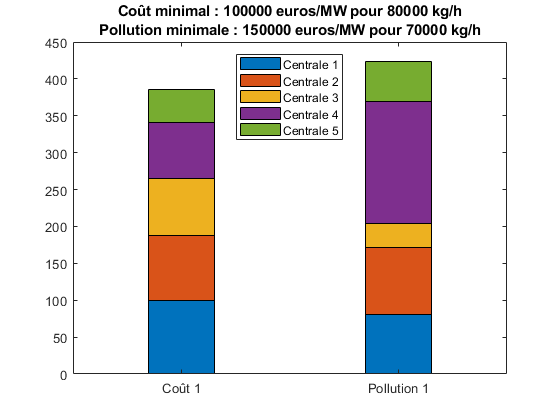

% exemple 2 (valeurs numériques aléatoires choisies)
x = categorical([{'Coût 1'}, {'Pollution 1'}]);
P = [100 88 77 76 45];
Q = [81 90 33 165 54];
C1=1e5; Pol1=8e4; C2=1.5e5; Pol2=7e4;
bar(x,[P;Q],0.3,'stacked')
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")
title(sprintf('Coût minimal : %3.0f euros/MW pour %4.0f kg/h\nPollution minimale : %3.0f euros/MW pour %4.0f kg/h',...
    C1,Pol1,C2,Pol2))

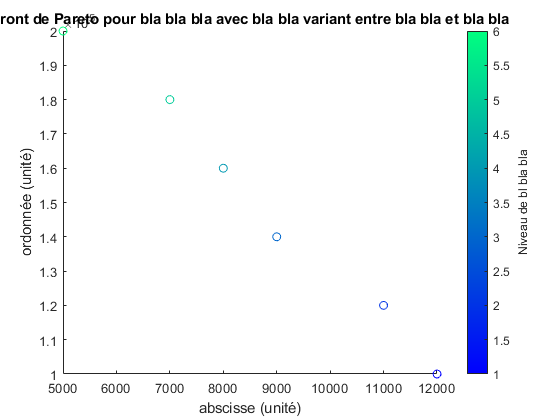

% exemple 3 (valeurs numériques aléatoires choisies)
X=1e5:0.2e5:2e5;
Y=[12 11 9 8 7 5].*1e3;
Z=1:6;
scatter(Y,X,[],Z)
colormap winter
c = colorbar;
c.Label.String = 'Niveau de bl bla bla';
xlabel('abscisse (unité)')
ylabel('ordonnée (unité)')
title('Front de Pareto pour bla bla bla avec bla bla variant entre bla bla et bla bla')